%importing audiofile 
[y, Fs] = audioread("beethoven_5th_sample.wav");
%sound(y, Fs) %playing the audio signal

pow = pow2(floor(log2(length(y)))); %truncating the signal to the nearest power of 2 
left_y = y(1:pow, 1);   %seperating left and right stereo chanels 
right_y = y(1:pow,2);

%plotting original signal 
y = y(1:pow)

y =     0.0031    0.0032    0.0030    0.0031    0.0031    0.0031    0.0030    0.0032    0.0030    0.0031    0.0030    0.0031    0.0030    0.0031    0.0030    0.0031    0.0030    0.0029    0.0031    0.0031    0.0032    0.0029    0.0030    0.0030    0.0029    0.0032    0.0031    0.0030    0.0031    0.0030    0.0030    0.0031    0.0030    0.0031    0.0030    0.0030    0.0031    0.0029    0.0033    0.0029    0.0031    0.0029    0.0032    0.0029    0.0031    0.0030    0.0030    0.0030    0.0031    0.0031


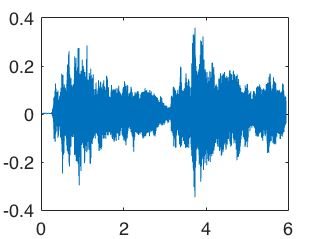

t = (0:pow-1)/Fs;
plot(t, y)

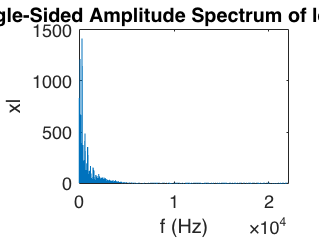



%performing Myfft on both chanels 
xr = Myfft(right_y);
xl = Myfft(left_y);

%creating single sided ffts
xr_ss = xr(1:pow/2);
xl_ss = xl(1:pow/2);

%creating frequency vector for single sided fft
fss = Fs*(0:(pow/2)-1)/pow;


%creating frequency vector for double sided fft
f = Fs*(0:(pow)-1)/pow;

%plotting single sided ffts 
plot(fss,abs(xl_ss)) 
title('Single-Sided Amplitude Spectrum of left signal')
xlabel('f (Hz)')
ylabel('xl')

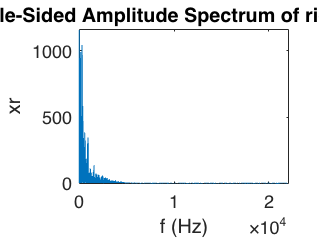

plot(fss,abs(xr_ss)) 
title('Single-Sided Amplitude Spectrum of right signal')
xlabel('f (Hz)')
ylabel('xr')

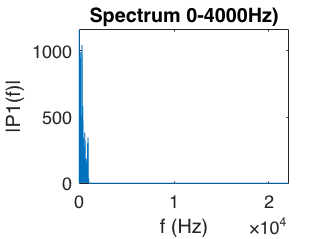


%creating the cutoff 
freq = 1000; %cutoff frequency
num = round(freq*pow/Fs); %index of the cutoff frequency in the sample
xr_ss(1, num:pow/2)=0; %setting all values in the fft that are passed 
xl_ss(1, num:pow/2)=0; %the cutoff value to 0

%plotting cutoff ffts to visually verify process
plot(fss, abs(xr_ss))
title('Spectrum 0-4000Hz)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

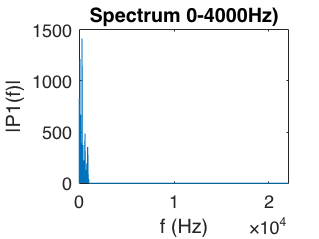


plot(fss, abs(xl_ss))
title('Spectrum 0-4000Hz)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

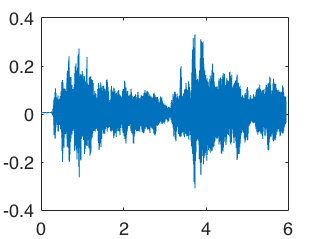


% perforing inverse fft on double sided
Y = ifft([xl_ss zeros(1, pow/2)]);
plot(t, 2*real(Y)) %playing 2 times the signal because, using the one sided fft cut the amplitude by two


sound(2*real(Y), Fs) % playing the sounds cut at the cutoff freq


